# **RS-HL-15-2: Multi User Simulation**

**UT Austin Oden Institute**

**Hongseok Kim**

**07/29/2024**

### I. Load the SAT-to-SAT dataset

% clear;clc;
% % Load the Satellite Contat Dataset
% addpath('~/Desktop/Redstone_Project/RS_HL/RS_HL_10_TV_MDP_Functions')
% load('~/RS_Dataset/RS_HL_3_dataset.mat')

### II.Destination Setting and Time Index Vector Setting

% % Parameter Setting
% % time_index_vector = 100:130;
% % start_time_index = 100:120;
% % state_vector = 1:48;
% % 
% % start_state = [3,3,3,3];
% % destination_state = [38, 38, 38, 38];
% % start_time = [100, 100, 100, 100];
% % 
% % simulation_input = [start_time', start_state', destination_state'];
% % number_of_simulation = length(simulation_input(:,1));

% 
% time_index_vector = 100:130;
% start_time_index = 100:120;
% % number_of_agents = 20;
% % number_of_destinations = 4;
% state_vector = 1:48;
% % 
% % 
% % start_state = state_vector(randi(numel(state_vector), 1, number_of_agents));
% % destination_values = randsample(state_vector,number_of_destinations);
% % destination_state = destination_values(randi(numel(destination_values), 1, number_of_agents));
% % start_time = start_time_index(randi(numel(start_time_index), 1, number_of_agents));
% 
% % Destination Values
% destination_values = [45, 2, 41, 32];
% 
% % Destination State
% destination_state = [41, 45, 41, 45, 2, 45, 45, 32, 41, 2, 32, 45, 2, 2, 32, 32, 45, 2, 2, 41];
% 
% % Start Time
% start_time = [114, 115, 105, 114, 113, 103, 102, 110, 120, 107, 112, 104, 115, 105, 110, 114, 118, 120, 111, 102];
% 
% % Agents Input
% agents_input = [
%     114, 40, 41;
%     115, 44, 45;
%     105, 7, 41;
%     114, 44, 45;
%     113, 31, 2;
%     103, 5, 45;
%     102, 14, 45;
%     110, 27, 32;
%     120, 46, 41;
%     107, 47, 2;
%     112, 8, 32;
%     104, 47, 45;
%     115, 46, 2;
%     105, 24, 2;
%     110, 39, 32;
%     114, 7, 32;
%     118, 21, 45;
%     120, 44, 2;
%     111, 39, 2;
%     102, 47, 41
% ];
% start_state = agents_input(:,2);
% 
% % simulation_input = [start_time', start_state', destination_state'];
% number_of_simulation = length(simulation_input(:,1));

### III. Run the MDP simulation

% simulation_result = struct();
% MDP = struct();
% 
% fprintf('Total Number of Simulations: %d\n', number_of_simulation);
% for simulation_index = 1:number_of_simulation
% 
%     if simulation_index == 1
%         sat_to_sat_matrix = sat_to_sat_contact_3d_matrix;
%     else
%         sat_to_sat_matrix = sat_to_sat_matrix_updated;
%     end
% 
%     fprintf('--------------------------------------\n')
%     fprintf('Running MDP %d / %d , Destination %d \n', simulation_index,number_of_simulation,destination_state(simulation_index));
% 
%     % Run the MDP
%     MDP.(['MDP',num2str(simulation_index)]) = runMDP(sat_to_sat_matrix, time_index_vector,destination_state(simulation_index)); 
%     [time_list, reward_list, state_list, state_value_list]= simulation_test(start_time(simulation_index),start_state(simulation_index), MDP.(['MDP',num2str(simulation_index)]),time_index_vector,destination_state(simulation_index));
% 
%     % Record ths simulation result
%     simulation_result.(['simulation',num2str(simulation_index)]).result = [time_list,  state_list,reward_list, state_value_list];
% 
% 
% 
%     number_of_states = length(state_vector);
%     state_value_over_time = zeros(length(time_index_vector),number_of_states);
%     for t = 1:length(time_index_vector)
%         for state_index = 1:number_of_states
%             state_value_over_time(t,state_index) = MDP.(['MDP',num2str(simulation_index)]).(['time' num2str(time_index_vector(t))]).(['state' num2str(state_index)]).('state_value');            
%         end
%     end
% 
%     simulation_result.(['simulation',num2str(simulation_index)]).state_value_over_time = state_value_over_time;
% 
% 
%     % Update the sat_to_sat_matrix
%     sat_to_sat_matrix_updated = sat_to_sat_matrix;
% 
%     for index = 2:length(time_list)
% 
%     time_index = time_list(index);
%     state_index = state_list(index);
% 
%     % sat_to_sat_matrix_updated(state_index,:,time_index) = 0;
%     sat_to_sat_matrix_updated(:,state_index,time_index-1) = 0;
%     % sat_to_sat_matrix_updated(state_index,state_index,time_index) = 1;
% 
%     % sat_to_sat_matrix_updated(state_index,:,time_index+1) = 0;
%     % sat_to_sat_matrix_updated(:,state_index,time_index+1) = 0;   
%     % sat_to_sat_matrix_updated(state_index,state_index,time_index+1) = 1;
%     end  
% end
% 
% fprintf('--------------------------------------\n')

### IV. State Value By Each Simulation

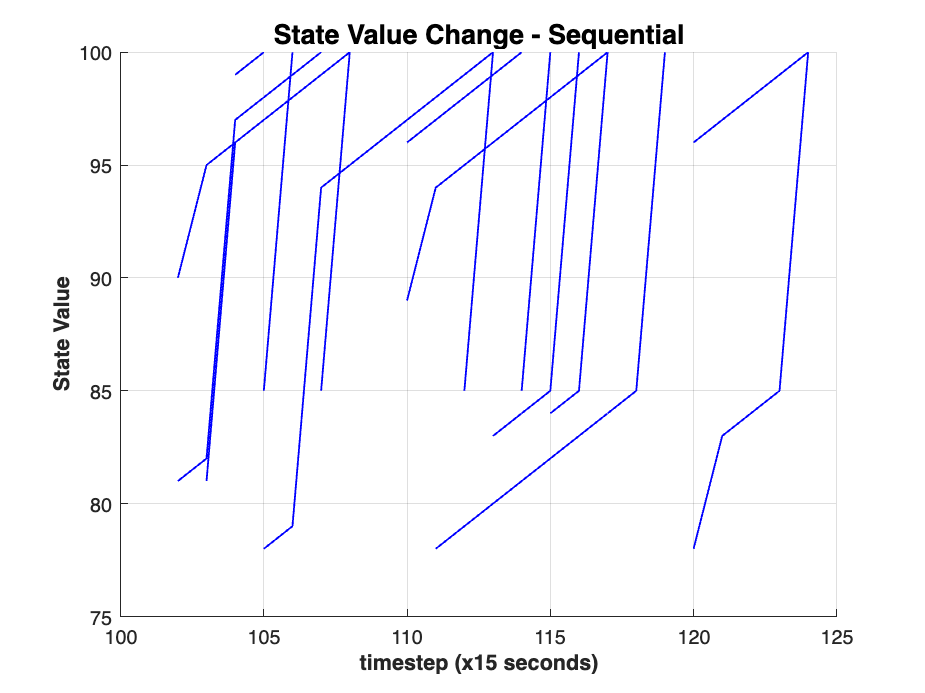

figure;
hold on
for simulation_index = 1:number_of_simulation
    result = simulation_result.(['simulation',num2str(simulation_index)]).result;
    result = result(result(:,4)~=0,:);
    plot(result(:,1),result(:,4),'color','b','LineWidth',1,'DisplayName',sprintf('sim %d', simulation_index))
end
hold off
title('State Value Change - Sequential','FontSize',15,'FontWeight','bold')
grid on

xlabel('timestep (x15 seconds)','FontSize',12,'FontWeight','bold')
ylabel('State Value','FontSize',12,'FontWeight','bold')

% legend('show','Location','northwest')

### V. Reward Value By Each Simulation

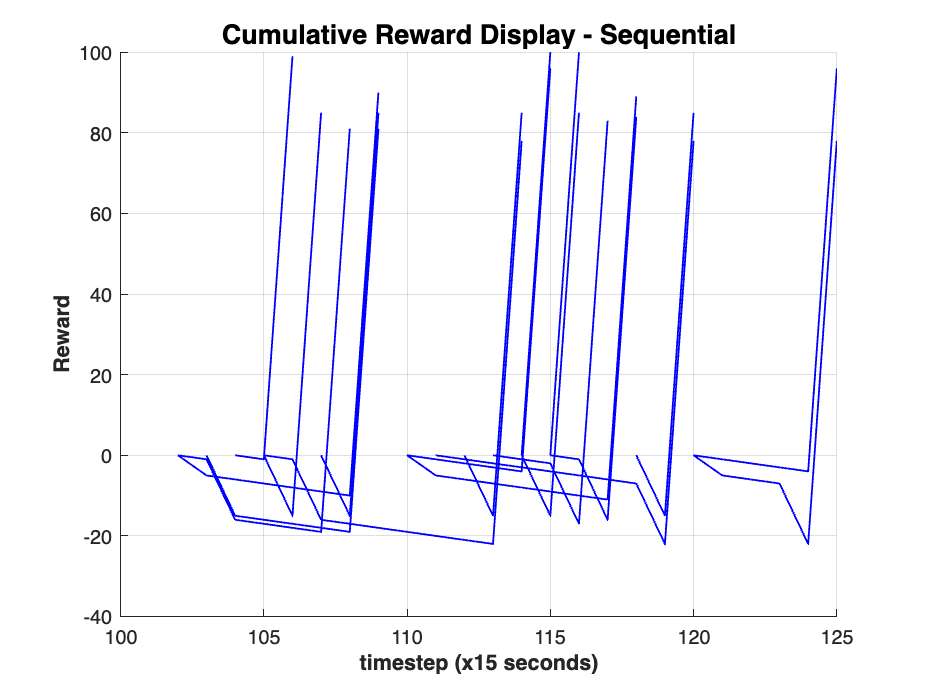

number_of_agents = 20;
final_cumulative_reward_vector = zeros(number_of_agents,1);

figure;
hold on
for simulation_index = 1:number_of_simulation
    result = simulation_result.(['simulation',num2str(simulation_index)]).result;
    final_cumulative_reward_vector(simulation_index) = result(end,3);
    plot(result(:,1),result(:,3),'color','b','LineWidth',1,'DisplayName',sprintf('sim %d', simulation_index))
end
hold off
title('Cumulative Reward Display - Sequential','FontSize',15,'FontWeight','bold')
grid on
xlabel('timestep (x15 seconds)','FontSize',12,'FontWeight','bold')
ylabel('Reward','FontSize',12,'FontWeight','bold')

% legend('show','Location','northwest')

### VI. Reward Value Histogram

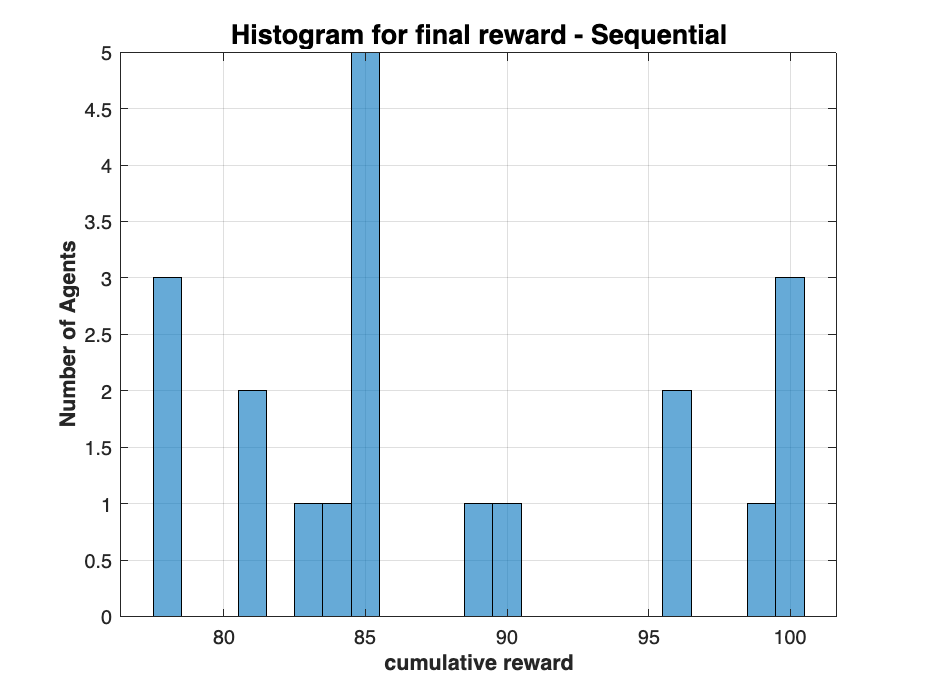

figure;
histogram(final_cumulative_reward_vector)
grid on
title('Histogram for final reward - Sequential','FontSize',15,'FontWeight','bold')
xlabel('cumulative reward','FontSize',12,'FontWeight','bold')
ylabel('Number of Agents','FontSize',12,'FontWeight','bold')


mean = mean(final_cumulative_reward_vector)

mean = 87.9000

standard_deviation = std(final_cumulative_reward_vector)

standard_deviation = 7.8466